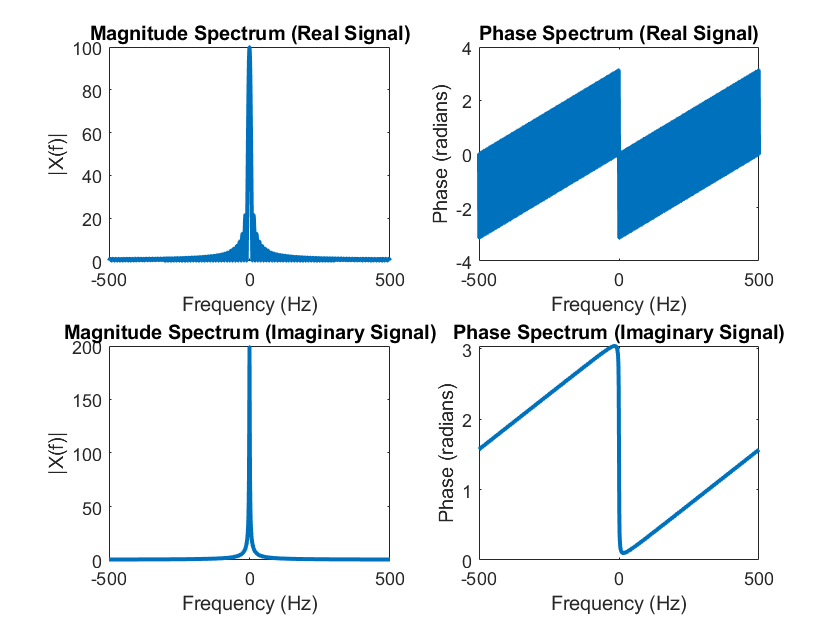

% Parameters
fs = 1000;  % Sampling frequency
T = 1/fs;   % Sampling period
t = 0:T:1;  % Time vector

% Pure Real Signal (Rectangular Pulse)
x_real = rectpuls(t - 0.5, 0.1);  % Rectangular pulse centered at 0.5s

% Pure Imaginary Signal (Decaying Exponential)
alpha = 5;  % Decay rate
x_imag = 1i * exp(-alpha * t);  % Pure imaginary signal

% Fourier Transform
frequencies = linspace(-fs/2, fs/2, length(t));
X_real = fftshift(fft(x_real));
X_imag = fftshift(fft(x_imag));

% Plotting the Fourier Transform magnitude and phase for the real signal
figure;

subplot(2, 2, 1);
plot(frequencies, abs(X_real), 'LineWidth', 2);
title('Magnitude Spectrum (Real Signal)');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');

subplot(2, 2, 2);
plot(frequencies, angle(X_real), 'LineWidth', 2);
title('Phase Spectrum (Real Signal)');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');

% Plotting the Fourier Transform magnitude and phase for the imaginary signal
subplot(2, 2, 3);
plot(frequencies, abs(X_imag), 'LineWidth', 2);
title('Magnitude Spectrum (Imaginary Signal)');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');

subplot(2, 2, 4);
plot(frequencies, angle(X_imag), 'LineWidth', 2);
title('Phase Spectrum (Imaginary Signal)');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');

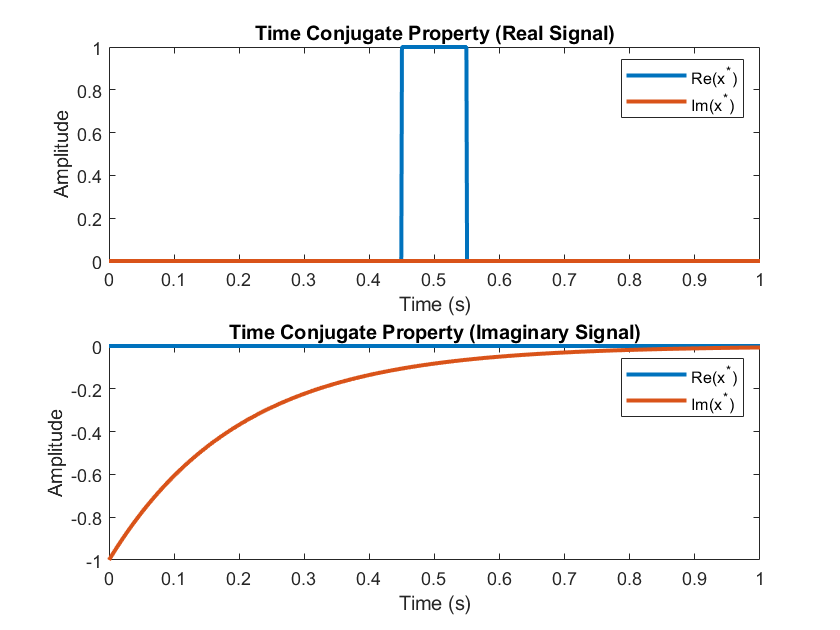


% Verifying Time Conjugate Property
figure;
subplot(2, 1, 1);
plot(t, real(conj(x_real)), 'LineWidth', 2);
hold on;
plot(t, imag(conj(x_real)), 'LineWidth', 2);
title('Time Conjugate Property (Real Signal)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Re(x^*)', 'Im(x^*)');
hold off;

subplot(2, 1, 2);
plot(t, real(conj(x_imag)), 'LineWidth', 2);
hold on;
plot(t, imag(conj(x_imag)), 'LineWidth', 2);
title('Time Conjugate Property (Imaginary Signal)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Re(x^*)', 'Im(x^*)');
hold off;